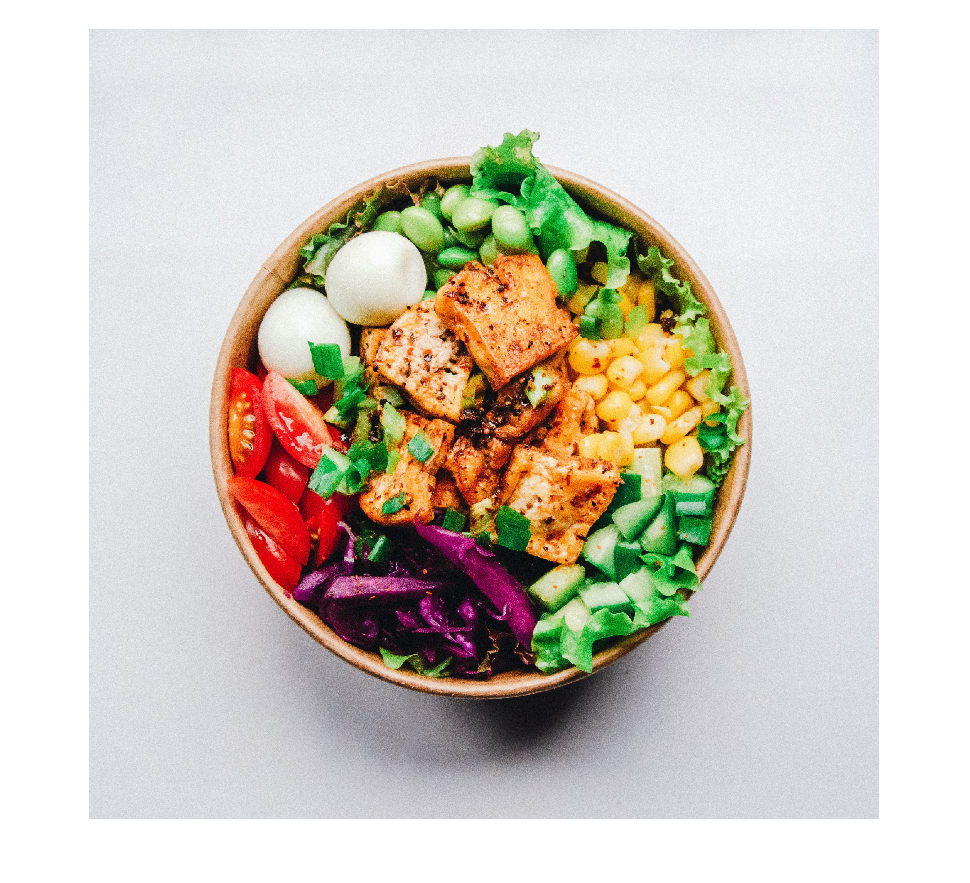

%%This matlab script will be used for experimenting with food
%%classification functions

image = imread('images/normal/VariedSalad.jpg');

green = Green(image);
lightGreen = LightGreen(image);
red = MoreRed(image);
yellow = Yellow(image);
purple = Purple(image);
orange = Orange(image);

greenResult = imfuse(lightGreen,green,'blend');

result = imfuse(greenResult, red,'diff');
result = imfuse(yellow,result,'diff');
result = imfuse(purple,result,'diff');
result = imfuse(orange, result,'diff');

rough = strel('disk',2);
roughProcessed = imopen(result,rough);
fused = imfuse(image,roughProcessed,'blend');

imshow(image)

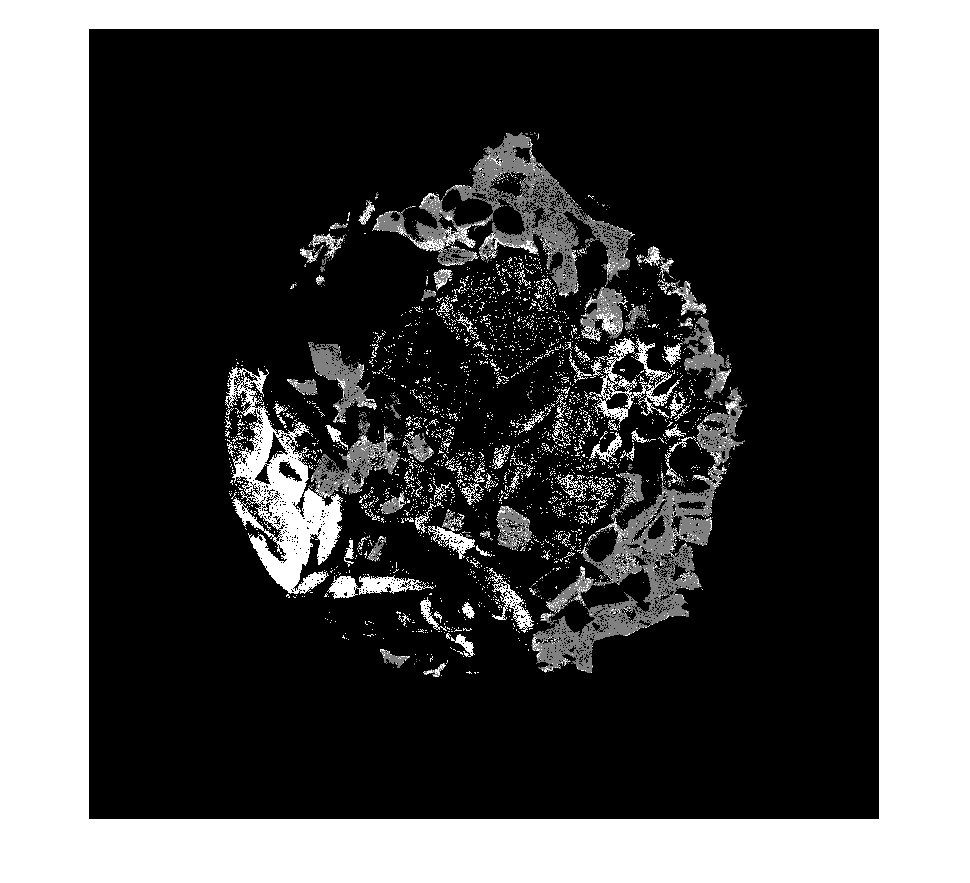

imshow(result)

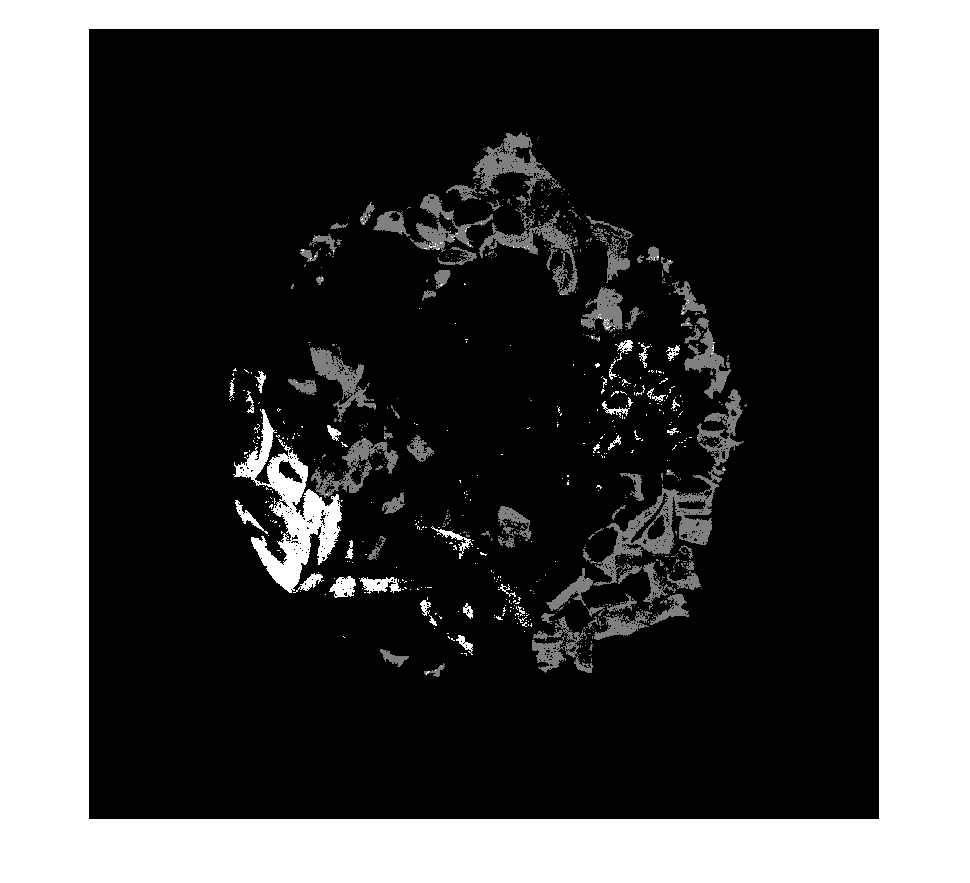

imshow(roughProcessed)

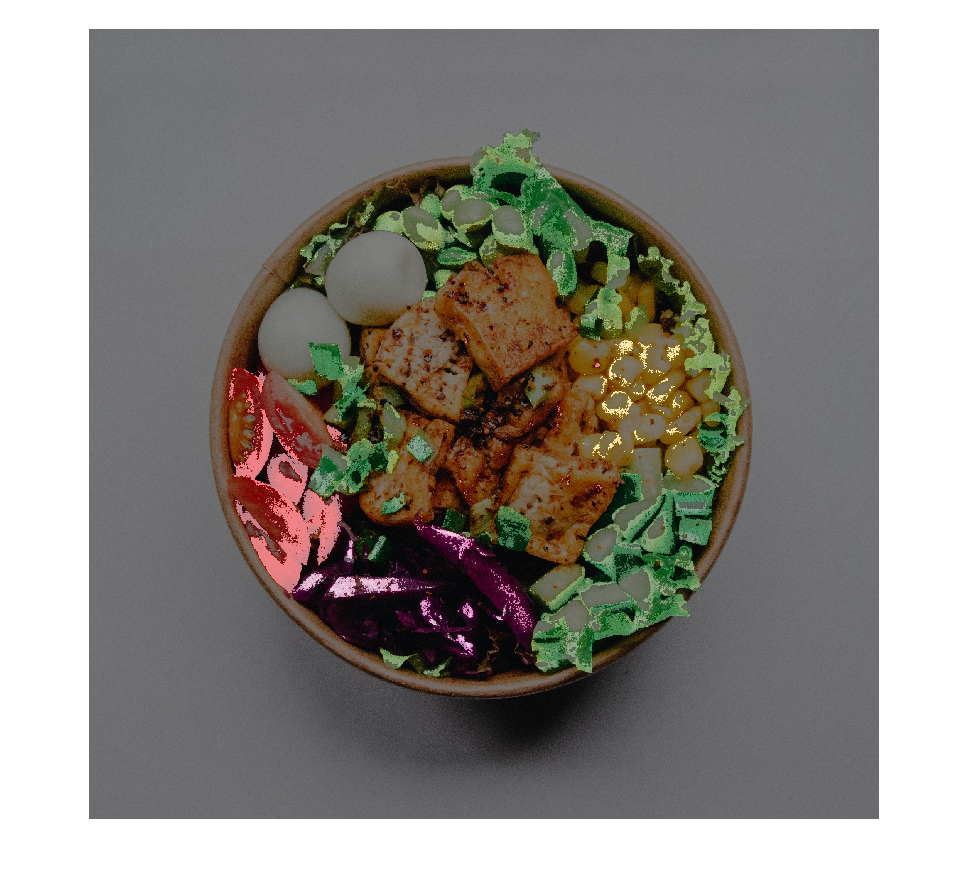

imshow(fused)